n=length(scheduler);
t=0;
q=0; %entry scheduler
n_accomplished=0; %numero richieste compiute
queue_size=0; %numero di richieste in coda
x=0; % contatore per valutare 30% scheduler

% plot_w = 1; % variabile booleana per considerare nei plot solo uno degli istanti di poisson (se multipli)
% w1=1; % index reputation malicious node 1
% w2=1; % index reputation malicious node 2
% w3=1; % index reputation malicious node 3
% w4=1; % index reputation malicious node 4
% w5=1; % index reputation malicious mean
% g=1;  % index reputation good_node
% z1=1; % index richieste compiute o in coda 

plot_w = 0; % variabile booleana per considerare nei plot solo uno degli istanti di poisson (se multipli)
w1=0; % index reputation malicious node 1
w2=0; % index reputation malicious node 2
w3=0; % index reputation malicious node 3
w4=0; % index reputation malicious node 4
w5=0; % index reputation malicious mean
g=0;  % index reputation good_node
z1=0; % index richieste compiute o in coda


repChange = 1;

%feed_neg=[14,42,47,84,76,5,82,20,74,27]; % vettore dei 10 nodi malevoli

%feed_neg=[1,7,13,25]; % vettore dei 4 nodi malevoli (25 device)
%feed_neg=[8,47,41,34,50]; % vettore dei 5 nodi malevoli (50 device)
%feed_neg=[65,20,7,27,64,47,1]; % vettore dei 8 nodi malevoli (75 device)
%feed_neg=[20,40,47,80,63,65,78,21,47,100]; % vettore dei 10 nodi malevoli (100 device)

seed_mal = 3;
rng(seed_mal);
feed_neg=randperm(D); %estrae il dieci percento dei nodi
feed_neg=feed_neg(1:floor(D/10));


    %while(numeroServiziEseguitiCorrettamente == numeroServiziDefinitiInizzial )
    %...
    % t = t+1;   
    % ultimo servizio degli schedulati ->
    %end
    
while(n_accomplished < length(scheduler) && t < 2000)

%while(t < 1500)
%tic; 
    %s1=1;    
        
    newIndex = find([scheduler.time] == t); %vettore degli indici di scheduler in cui scheduler.time==t
    if repChange == 1
            % circa 12 sec
            tic;
            reputation_order1(); %ordina per valore di reputation
            if (check_QoS == 1)  %(Dean)
                QoS_order1();    %(Dean) ordina per valore QoS
            end
%             switch check_QoS %(Dean) 
%                     case 0       % non fare nulla
%                     
%                     case 1       %% ordina i sp in base alla QoS, se non ce' un QoS_sp>QoS_sr allora prendi il piu' alto QoS
%                             QoS_order1();
%                     
%             end
            
            
            repChange = 0;            
            toc;
    end
    for s=newIndex
        plot_w =1;
        switch check_resource % interruttore per check resource capability 
            case 0 %% prende il primo della lista %(Dean) aggiunta sp_QoS e sr_QoS
                    [energy_sp,id_sp,energy_res,time_p,time_service,cost_service,id_serv,id_sr,id_master,sp_QoS,sr_QoS]=resource_control1(s,scheduler,service_array,device_array);
            case 1 %% prende il primo provider che ha capacità restante
                    [energy_sp,id_sp,energy_res,time_p,time_service,cost_service,id_serv,id_sr,id_master,sp_QoS,sr_QoS]=resource_control2(s,scheduler,service_array,device_array);
        end
        
     
       
       
        update(); % aggiorna l'energia residua
%         if(q>=1) % se il servizio è terminato
%            scheduler_temp=sort_scheduler_temp(scheduler_temp);
%            scheduler=sort_scheduler(scheduler);
%         end
        x=x+1;
    end
    
    %if w == true
    if plot_w ==1 %%???
       malicious_node1();
       malicious_node2();
       malicious_node3();
       malicious_node4();
       mean_malicious();       
       good_nodes();
       accomplished_queue();
    end
    
    
    if(q>=1) % se lo scheduler temporaneo presenta almeno una entry esegue il check
        % se almeno un task è stato completato
    newIndex1 = find([scheduler_temp.time1] == t);  %vettore degli indici di scheduler temporaneo in cui scheduler_temp.time1==t
    for s1=newIndex1             
            %if(x<=(length(scheduler)*0.30)) % definisce 30% dello scheduler per la gestione dei nodi malevoli
            %   master_array(scheduler_temp(s1).master).reputation=feedback(t,s1,master_array,scheduler_temp); 
            %   %assegnazione feedback e aggiornamento reputation (positivo o negativo)
            %   
            %   %update2(); % riassegnazione energia
            %else
               if(ismember(scheduler_temp(s1).sp1,feed_neg)==true && x > (length(scheduler)*0.30))
                  master_array(scheduler_temp(s1).master).reputation=negative_feedback(t,s1,master_array,scheduler_temp); 
                  %assegnazione feedback e aggiornamento reputation negativo
                  
                  %update2(); % riassegnazione energia
               else
                  master_array(scheduler_temp(s1).master).reputation=feedback(t,s1,master_array,scheduler_temp); 
                  %assegnazione feedback e aggiornamento reputation (positivo o negativo)
                 
                  %update2(); % riassegnazione energia
               end
               %end
            repChange = 1;
            update2();
    end
    end
    t=t+1;
    queue_array(t)=queue_size;
    disp(t);
    plot_w =0;
    % w = false;
    %toc;
end

Elapsed time is 0.086084 seconds.


     1

     2

     3

     4

     5

     6



Elapsed time is 0.608768 seconds.


     7



Elapsed time is 0.038421 seconds.


     8



Elapsed time is 0.158175 seconds.


     9



Elapsed time is 0.176629 seconds.


    10



Elapsed time is 0.384039 seconds.


    11



Elapsed time is 0.038851 seconds.


    12



Elapsed time is 0.023188 seconds.


    13



Elapsed time is 0.099964 seconds.


    14



Elapsed time is 0.054549 seconds.


    15



Elapsed time is 0.027804 seconds.


    16



Elapsed time is 0.044758 seconds.


    17



Elapsed time is 0.117871 seconds.


    18



Elapsed time is 0.155727 seconds.


    19



Elapsed time is 0.027517 seconds.


    20



Elapsed time is 0.076270 seconds.


    21



Elapsed time is 0.017539 seconds.


    22



Elapsed time is 0.042444 seconds.


    23



Elapsed time is 0.032196 seconds.


    24



Elapsed time is 0.054445 seconds.


    25



Elapsed time is 0.063356 seconds.


    26



Elapsed time is 0.089419 seconds.


    27



Elapsed time is 0.045051 seconds.


    28



Elapsed time is 0.057144 seconds.


    29



Elapsed time is 0.039794 seconds.


    30



Elapsed time is 0.081176 seconds.


    31



Elapsed time is 0.048993 seconds.


    32



Elapsed time is 0.058814 seconds.


    33



Elapsed time is 0.035032 seconds.


    34



Elapsed time is 0.057291 seconds.


    35



Elapsed time is 0.103003 seconds.


    36



Elapsed time is 0.097442 seconds.


    37



Elapsed time is 0.062458 seconds.


    38



Elapsed time is 0.065531 seconds.


    39



Elapsed time is 0.054141 seconds.


    40



Elapsed time is 0.072138 seconds.


    41



Elapsed time is 0.007158 seconds.


    42



Elapsed time is 0.062368 seconds.


    43



Elapsed time is 0.061470 seconds.


    44



Elapsed time is 0.060804 seconds.


    45



Elapsed time is 0.047834 seconds.


    46



Elapsed time is 0.114565 seconds.


    47



Elapsed time is 0.050767 seconds.


    48



Elapsed time is 0.051026 seconds.


    49



Elapsed time is 0.032749 seconds.


    50



Elapsed time is 0.062456 seconds.


    51



Elapsed time is 0.023449 seconds.


    52



Elapsed time is 0.028789 seconds.


    53



Elapsed time is 0.033385 seconds.


    54



Elapsed time is 0.037712 seconds.


    55



Elapsed time is 0.083476 seconds.


    56



Elapsed time is 0.039246 seconds.


    57



Elapsed time is 0.117585 seconds.


    58



Elapsed time is 0.055867 seconds.


    59



Elapsed time is 0.047774 seconds.


    60



Elapsed time is 0.066482 seconds.


    61



Elapsed time is 0.050069 seconds.


    62



Elapsed time is 0.076981 seconds.


    63



Elapsed time is 0.089031 seconds.


    64



Elapsed time is 0.045932 seconds.


    65



Elapsed time is 0.052745 seconds.


    66



Elapsed time is 0.080153 seconds.


    67



Elapsed time is 0.065366 seconds.


    68



Elapsed time is 0.105472 seconds.


    69



Elapsed time is 0.043495 seconds.


    70



Elapsed time is 0.037410 seconds.


    71



Elapsed time is 0.080181 seconds.


    72



Elapsed time is 0.085861 seconds.


    73



Elapsed time is 0.069201 seconds.


    74



Elapsed time is 0.123193 seconds.


    75



Elapsed time is 0.059808 seconds.


    76



Elapsed time is 0.152643 seconds.


    77



Elapsed time is 0.054091 seconds.


    78



Elapsed time is 0.058844 seconds.


    79



Elapsed time is 0.057390 seconds.


    80



Elapsed time is 0.061767 seconds.


    81



Elapsed time is 0.045214 seconds.


    82



Elapsed time is 0.058637 seconds.


    83



Elapsed time is 0.093414 seconds.


    84



Elapsed time is 0.067303 seconds.


    85



Elapsed time is 0.063718 seconds.


    86



Elapsed time is 0.071676 seconds.


    87



Elapsed time is 0.053400 seconds.


    88



Elapsed time is 0.099031 seconds.


    89



Elapsed time is 0.084647 seconds.


    90



Elapsed time is 0.056930 seconds.


    91



Elapsed time is 0.048391 seconds.


    92



Elapsed time is 0.064237 seconds.


    93



Elapsed time is 0.135932 seconds.


    94



Elapsed time is 0.153786 seconds.


    95



Elapsed time is 0.112868 seconds.


    96



Elapsed time is 0.100059 seconds.


    97



Elapsed time is 0.058488 seconds.


    98



Elapsed time is 0.116011 seconds.


    99



Elapsed time is 0.027209 seconds.


   100



Elapsed time is 0.123937 seconds.


   101



Elapsed time is 0.098053 seconds.


   102



Elapsed time is 0.094289 seconds.


   103



Elapsed time is 0.157350 seconds.


   104



Elapsed time is 0.054899 seconds.


   105



Elapsed time is 0.081258 seconds.


   106



Elapsed time is 0.096200 seconds.


   107



Elapsed time is 0.101600 seconds.


   108



Elapsed time is 0.031815 seconds.


   109



Elapsed time is 0.143951 seconds.


   110



Elapsed time is 0.106079 seconds.


   111



Elapsed time is 0.150514 seconds.


   112



Elapsed time is 0.093579 seconds.


   113



Elapsed time is 0.052192 seconds.


   114



Elapsed time is 0.000377 seconds.


   115



Elapsed time is 0.056836 seconds.


   116



Elapsed time is 0.062212 seconds.


   117



Elapsed time is 0.085349 seconds.


   118



Elapsed time is 0.114092 seconds.


   119



Elapsed time is 0.123524 seconds.


   120



Elapsed time is 0.147267 seconds.


   121



Elapsed time is 0.077891 seconds.


   122



Elapsed time is 0.112534 seconds.


   123



Elapsed time is 0.101247 seconds.


   124



Elapsed time is 0.057323 seconds.


   125



Elapsed time is 0.100553 seconds.


   126



Elapsed time is 0.112415 seconds.


   127



Elapsed time is 0.097669 seconds.


   128



Elapsed time is 0.075409 seconds.


   129



Elapsed time is 0.099469 seconds.


   130



Elapsed time is 0.129584 seconds.


   131



Elapsed time is 0.085849 seconds.


   132



Elapsed time is 0.117763 seconds.


   133



Elapsed time is 0.130976 seconds.


   134



Elapsed time is 0.116871 seconds.


   135



Elapsed time is 0.053068 seconds.


   136



Elapsed time is 0.082792 seconds.


   137



Elapsed time is 0.065719 seconds.


   138



Elapsed time is 0.083624 seconds.


   139



Elapsed time is 0.127386 seconds.


   140



Elapsed time is 0.071086 seconds.


   141



Elapsed time is 0.137585 seconds.


   142



Elapsed time is 0.093303 seconds.


   143



Elapsed time is 0.117340 seconds.


   144



Elapsed time is 0.188809 seconds.


   145



Elapsed time is 0.058232 seconds.


   146



Elapsed time is 0.091693 seconds.


   147



Elapsed time is 0.146736 seconds.


   148



Elapsed time is 0.153204 seconds.


   149



Elapsed time is 0.068969 seconds.


   150



Elapsed time is 0.143889 seconds.


   151



Elapsed time is 0.078966 seconds.


   152



Elapsed time is 0.080674 seconds.


   153



Elapsed time is 0.032632 seconds.


   154



Elapsed time is 0.090524 seconds.


   155



Elapsed time is 0.046425 seconds.


   156



Elapsed time is 0.098640 seconds.


   157



Elapsed time is 0.100372 seconds.


   158



Elapsed time is 0.103638 seconds.


   159



Elapsed time is 0.106531 seconds.


   160



Elapsed time is 0.056353 seconds.


   161



Elapsed time is 0.049530 seconds.


   162



Elapsed time is 0.141456 seconds.


   163



Elapsed time is 0.053376 seconds.


   164



Elapsed time is 0.076784 seconds.


   165



Elapsed time is 0.066294 seconds.


   166



Elapsed time is 0.107935 seconds.


   167



Elapsed time is 0.069808 seconds.


   168



Elapsed time is 0.098582 seconds.


   169



Elapsed time is 0.105052 seconds.


   170



Elapsed time is 0.090783 seconds.


   171



Elapsed time is 0.026123 seconds.


   172



Elapsed time is 0.110960 seconds.


   173



Elapsed time is 0.110291 seconds.


   174



Elapsed time is 0.097227 seconds.


   175



Elapsed time is 0.087538 seconds.


   176



Elapsed time is 0.112564 seconds.


   177



Elapsed time is 0.123322 seconds.


   178



Elapsed time is 0.081629 seconds.


   179



Elapsed time is 0.149269 seconds.


   180



Elapsed time is 0.092130 seconds.


   181



Elapsed time is 0.101154 seconds.


   182



Elapsed time is 0.032673 seconds.


   183



Elapsed time is 0.134288 seconds.


   184



Elapsed time is 0.089398 seconds.


   185



Elapsed time is 0.024643 seconds.


   186



Elapsed time is 0.095324 seconds.


   187



Elapsed time is 0.109709 seconds.


   188



Elapsed time is 0.082594 seconds.


   189



Elapsed time is 0.084267 seconds.


   190



Elapsed time is 0.066625 seconds.


   191



Elapsed time is 0.138436 seconds.


   192



Elapsed time is 0.111037 seconds.


   193



Elapsed time is 0.093172 seconds.


   194



Elapsed time is 0.093369 seconds.


   195



Elapsed time is 0.119046 seconds.


   196



Elapsed time is 0.112635 seconds.


   197



Elapsed time is 0.069091 seconds.


   198



Elapsed time is 0.069567 seconds.


   199



Elapsed time is 0.102592 seconds.


   200



Elapsed time is 0.143529 seconds.


   201



Elapsed time is 0.128466 seconds.


   202



Elapsed time is 0.107580 seconds.


   203



Elapsed time is 0.117614 seconds.


   204



Elapsed time is 0.031358 seconds.


   205



Elapsed time is 0.128246 seconds.


   206



Elapsed time is 0.115387 seconds.


   207



Elapsed time is 0.142780 seconds.


   208



Elapsed time is 0.050625 seconds.


   209



Elapsed time is 0.082236 seconds.


   210



Elapsed time is 0.073700 seconds.


   211



Elapsed time is 0.122405 seconds.


   212



Elapsed time is 0.109478 seconds.


   213



Elapsed time is 0.076659 seconds.


   214



Elapsed time is 0.129545 seconds.


   215



Elapsed time is 0.112809 seconds.


   216



Elapsed time is 0.129443 seconds.


   217



Elapsed time is 0.095934 seconds.


   218



Elapsed time is 0.149714 seconds.


   219



Elapsed time is 0.116584 seconds.


   220



Elapsed time is 0.062293 seconds.


   221



Elapsed time is 0.157408 seconds.


   222



Elapsed time is 0.174217 seconds.


   223



Elapsed time is 0.125551 seconds.


   224



Elapsed time is 0.104414 seconds.


   225



Elapsed time is 0.125519 seconds.


   226



Elapsed time is 0.095027 seconds.


   227



Elapsed time is 0.190279 seconds.


   228



Elapsed time is 0.081133 seconds.


   229



Elapsed time is 0.196721 seconds.


   230



Elapsed time is 0.148490 seconds.


   231



Elapsed time is 0.044681 seconds.


   232



Elapsed time is 0.094349 seconds.


   233



Elapsed time is 0.107939 seconds.


   234



Elapsed time is 0.132316 seconds.


   235



Elapsed time is 0.215394 seconds.


   236



Elapsed time is 0.143380 seconds.


   237



Elapsed time is 0.098562 seconds.


   238



Elapsed time is 0.126313 seconds.


   239



Elapsed time is 0.140229 seconds.


   240



Elapsed time is 0.098344 seconds.


   241



Elapsed time is 0.071255 seconds.


   242



Elapsed time is 0.170080 seconds.


   243



Elapsed time is 0.174702 seconds.


   244



Elapsed time is 0.149305 seconds.


   245



Elapsed time is 0.144495 seconds.


   246



Elapsed time is 0.223822 seconds.


   247



Elapsed time is 0.262066 seconds.


   248



Elapsed time is 0.045135 seconds.


   249



Elapsed time is 0.159646 seconds.


   250



Elapsed time is 0.206218 seconds.


   251



Elapsed time is 0.141993 seconds.


   252



Elapsed time is 0.189728 seconds.


   253



Elapsed time is 0.267999 seconds.


   254



Elapsed time is 0.069483 seconds.


   255



Elapsed time is 0.148392 seconds.


   256



Elapsed time is 0.141683 seconds.


   257



Elapsed time is 0.187569 seconds.


   258



Elapsed time is 0.137948 seconds.


   259



Elapsed time is 0.047525 seconds.


   260



Elapsed time is 0.258348 seconds.


   261



Elapsed time is 0.117804 seconds.


   262



Elapsed time is 0.178772 seconds.


   263



Elapsed time is 0.160742 seconds.


   264



Elapsed time is 0.211134 seconds.


   265



Elapsed time is 0.079899 seconds.


   266



Elapsed time is 0.073751 seconds.


   267



Elapsed time is 0.161805 seconds.


   268



Elapsed time is 0.188370 seconds.


   269



Elapsed time is 0.164166 seconds.


   270



Elapsed time is 0.220255 seconds.


   271



Elapsed time is 0.134079 seconds.


   272



Elapsed time is 0.105625 seconds.


   273



Elapsed time is 0.130377 seconds.


   274



Elapsed time is 0.200254 seconds.


   275



Elapsed time is 0.086058 seconds.


   276



Elapsed time is 0.116741 seconds.


   277



Elapsed time is 0.190867 seconds.


   278



Elapsed time is 0.168112 seconds.


   279



Elapsed time is 0.111278 seconds.


   280



Elapsed time is 0.138341 seconds.


   281



Elapsed time is 0.091178 seconds.


   282



Elapsed time is 0.213870 seconds.


   283



Elapsed time is 0.207756 seconds.


   284



Elapsed time is 0.127453 seconds.


   285



Elapsed time is 0.188880 seconds.


   286



Elapsed time is 0.122763 seconds.


   287



Elapsed time is 0.133312 seconds.


   288



Elapsed time is 0.117101 seconds.


   289



Elapsed time is 0.201433 seconds.


   290



Elapsed time is 0.100557 seconds.


   291



Elapsed time is 0.268314 seconds.


   292



Elapsed time is 0.132246 seconds.


   293



Elapsed time is 0.179743 seconds.


   294



Elapsed time is 0.196690 seconds.


   295



Elapsed time is 0.177759 seconds.


   296



Elapsed time is 0.155254 seconds.


   297



Elapsed time is 0.216699 seconds.


   298



Elapsed time is 0.115606 seconds.


   299



Elapsed time is 0.103244 seconds.


   300



Elapsed time is 0.122946 seconds.


   301



Elapsed time is 0.243902 seconds.


   302



Elapsed time is 0.170075 seconds.


   303



Elapsed time is 0.101770 seconds.


   304



Elapsed time is 0.115803 seconds.


   305



Elapsed time is 0.033748 seconds.


   306

   307



Elapsed time is 0.139161 seconds.


   308



Elapsed time is 0.216426 seconds.


   309



Elapsed time is 0.243637 seconds.


   310



Elapsed time is 0.221073 seconds.


   311



Elapsed time is 0.132228 seconds.


   312



Elapsed time is 0.100589 seconds.


   313



Elapsed time is 0.095734 seconds.


   314



Elapsed time is 0.148126 seconds.


   315



Elapsed time is 0.090148 seconds.


   316



Elapsed time is 0.076565 seconds.


   317



Elapsed time is 0.129037 seconds.


   318



Elapsed time is 0.034982 seconds.


   319



Elapsed time is 0.130587 seconds.


   320



Elapsed time is 0.129516 seconds.


   321



Elapsed time is 0.144999 seconds.


   322



Elapsed time is 0.109368 seconds.


   323



Elapsed time is 0.055273 seconds.


   324



Elapsed time is 0.233000 seconds.


   325



Elapsed time is 0.110715 seconds.


   326



Elapsed time is 0.210841 seconds.


   327



Elapsed time is 0.062061 seconds.


   328



Elapsed time is 0.165277 seconds.


   329



Elapsed time is 0.129569 seconds.


   330



Elapsed time is 0.095375 seconds.


   331



Elapsed time is 0.155878 seconds.


   332



Elapsed time is 0.105757 seconds.


   333



Elapsed time is 0.172353 seconds.


   334



Elapsed time is 0.182542 seconds.


   335



Elapsed time is 0.109589 seconds.


   336



Elapsed time is 0.026021 seconds.


   337



Elapsed time is 0.074820 seconds.


   338



Elapsed time is 0.056655 seconds.


   339



Elapsed time is 0.030400 seconds.


   340



Elapsed time is 0.056833 seconds.


   341



Elapsed time is 0.083044 seconds.


   342



Elapsed time is 0.129240 seconds.


   343



Elapsed time is 0.200459 seconds.


   344



Elapsed time is 0.132498 seconds.


   345



Elapsed time is 0.137446 seconds.


   346



Elapsed time is 0.085690 seconds.


   347



Elapsed time is 0.094861 seconds.


   348



Elapsed time is 0.172740 seconds.


   349



Elapsed time is 0.136310 seconds.


   350



Elapsed time is 0.135119 seconds.


   351



Elapsed time is 0.048775 seconds.


   352



Elapsed time is 0.064129 seconds.


   353



Elapsed time is 0.182926 seconds.


   354



Elapsed time is 0.086213 seconds.


   355



Elapsed time is 0.254336 seconds.


   356



Elapsed time is 0.072288 seconds.


   357



Elapsed time is 0.120966 seconds.


   358



Elapsed time is 0.093821 seconds.


   359



Elapsed time is 0.084202 seconds.


   360



Elapsed time is 0.135214 seconds.


   361



Elapsed time is 0.146212 seconds.


   362



Elapsed time is 0.139474 seconds.


   363



Elapsed time is 0.209541 seconds.


   364



Elapsed time is 0.160625 seconds.


   365



Elapsed time is 0.115176 seconds.


   366



Elapsed time is 0.124878 seconds.


   367



Elapsed time is 0.044658 seconds.


   368



Elapsed time is 0.101864 seconds.


   369



Elapsed time is 0.220597 seconds.


   370



Elapsed time is 0.021191 seconds.


   371



Elapsed time is 0.063389 seconds.


   372



Elapsed time is 0.174776 seconds.


   373



Elapsed time is 0.077880 seconds.


   374



Elapsed time is 0.155164 seconds.


   375



Elapsed time is 0.135007 seconds.


   376



Elapsed time is 0.136338 seconds.


   377



Elapsed time is 0.134358 seconds.


   378



Elapsed time is 0.071250 seconds.


   379



Elapsed time is 0.217454 seconds.


   380



Elapsed time is 0.311990 seconds.


   381



Elapsed time is 0.125161 seconds.


   382



Elapsed time is 0.148089 seconds.


   383



Elapsed time is 0.113274 seconds.


   384



Elapsed time is 0.135864 seconds.


   385



Elapsed time is 0.126340 seconds.


   386



Elapsed time is 0.150556 seconds.


   387



Elapsed time is 0.141584 seconds.


   388



Elapsed time is 0.159766 seconds.


   389



Elapsed time is 0.211115 seconds.


   390



Elapsed time is 0.150994 seconds.


   391



Elapsed time is 0.127816 seconds.


   392



Elapsed time is 0.069432 seconds.


   393



Elapsed time is 0.186393 seconds.


   394



Elapsed time is 0.200215 seconds.


   395



Elapsed time is 0.241972 seconds.


   396



Elapsed time is 0.108229 seconds.


   397



Elapsed time is 0.182849 seconds.


   398



Elapsed time is 0.082524 seconds.


   399



Elapsed time is 0.104992 seconds.


   400



Elapsed time is 0.069603 seconds.


   401



Elapsed time is 0.107612 seconds.


   402



Elapsed time is 0.269131 seconds.


   403



Elapsed time is 0.251646 seconds.


   404



Elapsed time is 0.084489 seconds.


   405



Elapsed time is 0.304404 seconds.


   406



Elapsed time is 0.182280 seconds.


   407



Elapsed time is 0.246083 seconds.


   408



Elapsed time is 0.147372 seconds.


   409



Elapsed time is 0.018189 seconds.


   410



Elapsed time is 0.211371 seconds.


   411



Elapsed time is 0.206167 seconds.


   412



Elapsed time is 0.215484 seconds.


   413



Elapsed time is 0.209861 seconds.


   414



Elapsed time is 0.046908 seconds.


   415



Elapsed time is 0.329761 seconds.


   416



Elapsed time is 0.095689 seconds.


   417



Elapsed time is 0.256130 seconds.


   418



Elapsed time is 0.021370 seconds.


   419



Elapsed time is 0.131419 seconds.


   420



Elapsed time is 0.156021 seconds.


   421



Elapsed time is 0.112258 seconds.


   422



Elapsed time is 0.205495 seconds.


   423



Elapsed time is 0.147032 seconds.


   424



Elapsed time is 0.044243 seconds.


   425



Elapsed time is 0.083906 seconds.


   426



Elapsed time is 0.135507 seconds.


   427



Elapsed time is 0.188664 seconds.


   428



Elapsed time is 0.216140 seconds.


   429



Elapsed time is 0.255410 seconds.


   430



Elapsed time is 0.202564 seconds.


   431



Elapsed time is 0.214518 seconds.


   432



Elapsed time is 0.219389 seconds.


   433



Elapsed time is 0.233894 seconds.


   434



Elapsed time is 0.134064 seconds.


   435



Elapsed time is 0.204932 seconds.


   436



Elapsed time is 0.118379 seconds.


   437



Elapsed time is 0.127081 seconds.


   438



Elapsed time is 0.142444 seconds.


   439



Elapsed time is 0.102676 seconds.


   440



Elapsed time is 0.185327 seconds.


   441



Elapsed time is 0.203273 seconds.


   442



Elapsed time is 0.107854 seconds.


   443



Elapsed time is 0.269948 seconds.


   444



Elapsed time is 0.049215 seconds.


   445



Elapsed time is 0.200559 seconds.


   446



Elapsed time is 0.136200 seconds.


   447



Elapsed time is 0.096030 seconds.


   448



Elapsed time is 0.188268 seconds.


   449



Elapsed time is 0.157936 seconds.


   450



Elapsed time is 0.228911 seconds.


   451



Elapsed time is 0.186122 seconds.


   452



Elapsed time is 0.258667 seconds.


   453



Elapsed time is 0.326359 seconds.


   454



Elapsed time is 0.166496 seconds.


   455



Elapsed time is 0.109761 seconds.


   456



Elapsed time is 0.221316 seconds.


   457



Elapsed time is 0.216668 seconds.


   458



Elapsed time is 0.217220 seconds.


   459



Elapsed time is 0.048931 seconds.


   460



Elapsed time is 0.174009 seconds.


   461



Elapsed time is 0.284330 seconds.


   462



Elapsed time is 0.108558 seconds.


   463



Elapsed time is 0.141877 seconds.


   464



Elapsed time is 0.164372 seconds.


   465



Elapsed time is 0.122311 seconds.


   466



Elapsed time is 0.094546 seconds.


   467



Elapsed time is 0.175358 seconds.


   468



Elapsed time is 0.084309 seconds.


   469



Elapsed time is 0.026607 seconds.


   470



Elapsed time is 0.148330 seconds.


   471



Elapsed time is 0.154099 seconds.


   472



Elapsed time is 0.271623 seconds.


   473



Elapsed time is 0.050411 seconds.


   474



Elapsed time is 0.317395 seconds.


   475



Elapsed time is 0.137640 seconds.


   476



Elapsed time is 0.182190 seconds.


   477



Elapsed time is 0.135539 seconds.


   478



Elapsed time is 0.218912 seconds.


   479



Elapsed time is 0.098678 seconds.


   480



Elapsed time is 0.275072 seconds.


   481



Elapsed time is 0.049469 seconds.


   482



Elapsed time is 0.177969 seconds.


   483



Elapsed time is 0.183234 seconds.


   484



Elapsed time is 0.210929 seconds.


   485



Elapsed time is 0.256694 seconds.


   486



Elapsed time is 0.158275 seconds.


   487



Elapsed time is 0.091070 seconds.


   488



Elapsed time is 0.100166 seconds.


   489



Elapsed time is 0.092180 seconds.


   490



Elapsed time is 0.158197 seconds.


   491



Elapsed time is 0.309559 seconds.


   492



Elapsed time is 0.162956 seconds.


   493



Elapsed time is 0.134967 seconds.


   494



Elapsed time is 0.198869 seconds.


   495



Elapsed time is 0.236879 seconds.


   496



Elapsed time is 0.306679 seconds.


   497



Elapsed time is 0.061203 seconds.


   498



Elapsed time is 0.330039 seconds.


   499



Elapsed time is 0.132350 seconds.


   500



Elapsed time is 0.193559 seconds.


   501



Elapsed time is 0.121318 seconds.


   502



Elapsed time is 0.240898 seconds.


   503



Elapsed time is 0.274590 seconds.


   504



Elapsed time is 0.153099 seconds.


   505



Elapsed time is 0.273853 seconds.


   506



Elapsed time is 0.191821 seconds.


   507



Elapsed time is 0.168469 seconds.


   508



Elapsed time is 0.134808 seconds.


   509



Elapsed time is 0.220766 seconds.


   510



Elapsed time is 0.060314 seconds.


   511



Elapsed time is 0.095306 seconds.


   512



Elapsed time is 0.191016 seconds.


   513



Elapsed time is 0.297553 seconds.


   514



Elapsed time is 0.059264 seconds.


   515



Elapsed time is 0.118855 seconds.


   516



Elapsed time is 0.252386 seconds.


   517



Elapsed time is 0.104650 seconds.


   518



Elapsed time is 0.174245 seconds.


   519



Elapsed time is 0.200060 seconds.


   520



Elapsed time is 0.134087 seconds.


   521



Elapsed time is 0.185735 seconds.


   522



Elapsed time is 0.361508 seconds.


   523



Elapsed time is 0.122060 seconds.


   524



Elapsed time is 0.157849 seconds.


   525



Elapsed time is 0.240435 seconds.


   526



Elapsed time is 0.235884 seconds.


   527



Elapsed time is 0.292346 seconds.


   528



Elapsed time is 0.151149 seconds.


   529



Elapsed time is 0.239421 seconds.


   530



Elapsed time is 0.213813 seconds.


   531



Elapsed time is 0.179797 seconds.


   532



Elapsed time is 0.105555 seconds.


   533



Elapsed time is 0.253209 seconds.


   534



Elapsed time is 0.145838 seconds.


   535



Elapsed time is 0.142705 seconds.


   536



Elapsed time is 0.276444 seconds.


   537



Elapsed time is 0.028175 seconds.


   538



Elapsed time is 0.223134 seconds.


   539



Elapsed time is 0.106064 seconds.


   540



Elapsed time is 0.224048 seconds.


   541



Elapsed time is 0.074133 seconds.


   542



Elapsed time is 0.143765 seconds.


   543



Elapsed time is 0.224098 seconds.


   544



Elapsed time is 0.295817 seconds.


   545

   546



Elapsed time is 0.092408 seconds.


   547



Elapsed time is 0.105238 seconds.


   548



Elapsed time is 0.196371 seconds.


   549



Elapsed time is 0.158920 seconds.


   550



Elapsed time is 0.233588 seconds.


   551



Elapsed time is 0.165986 seconds.


   552



Elapsed time is 0.211261 seconds.


   553



Elapsed time is 0.253406 seconds.


   554



Elapsed time is 0.259859 seconds.


   555



Elapsed time is 0.111992 seconds.


   556



Elapsed time is 0.341401 seconds.


   557



Elapsed time is 0.197747 seconds.


   558



Elapsed time is 0.224030 seconds.


   559



Elapsed time is 0.168989 seconds.


   560



Elapsed time is 0.151014 seconds.


   561



Elapsed time is 0.189946 seconds.


   562



Elapsed time is 0.321313 seconds.


   563



Elapsed time is 0.224050 seconds.


   564



Elapsed time is 0.378092 seconds.


   565



Elapsed time is 0.189233 seconds.


   566



Elapsed time is 0.062635 seconds.


   567



Elapsed time is 0.146398 seconds.


   568



Elapsed time is 0.165228 seconds.


   569



Elapsed time is 0.215839 seconds.


   570



Elapsed time is 0.200505 seconds.


   571



Elapsed time is 0.113231 seconds.


   572



Elapsed time is 0.235377 seconds.


   573



Elapsed time is 0.126531 seconds.


   574



Elapsed time is 0.166846 seconds.


   575



Elapsed time is 0.145908 seconds.


   576



Elapsed time is 0.188676 seconds.


   577



Elapsed time is 0.068778 seconds.


   578



Elapsed time is 0.233273 seconds.


   579



Elapsed time is 0.266617 seconds.


   580



Elapsed time is 0.171081 seconds.


   581



Elapsed time is 0.153724 seconds.


   582



Elapsed time is 0.260110 seconds.


   583



Elapsed time is 0.158469 seconds.


   584



Elapsed time is 0.162358 seconds.


   585



Elapsed time is 0.202628 seconds.


   586



Elapsed time is 0.178359 seconds.


   587



Elapsed time is 0.200750 seconds.


   588



Elapsed time is 0.477691 seconds.


   589



Elapsed time is 0.155947 seconds.


   590



Elapsed time is 0.374082 seconds.


   591



Elapsed time is 0.124202 seconds.


   592



Elapsed time is 0.276219 seconds.


   593



Elapsed time is 0.200121 seconds.


   594



Elapsed time is 0.180200 seconds.


   595



Elapsed time is 0.270645 seconds.


   596



Elapsed time is 0.207473 seconds.


   597



Elapsed time is 0.356284 seconds.


   598



Elapsed time is 0.243383 seconds.


   599



Elapsed time is 0.461410 seconds.


   600



Elapsed time is 0.395678 seconds.


   601



Elapsed time is 0.108909 seconds.


   602



Elapsed time is 0.079822 seconds.


   603



Elapsed time is 0.151689 seconds.


   604



Elapsed time is 0.137744 seconds.


   605



Elapsed time is 0.098696 seconds.


   606



Elapsed time is 0.093362 seconds.


   607



Elapsed time is 0.035715 seconds.


   608



Elapsed time is 0.093090 seconds.


   609



Elapsed time is 0.086310 seconds.


   610



Elapsed time is 0.023627 seconds.


   611



Elapsed time is 0.031409 seconds.


   612



Elapsed time is 0.104132 seconds.


   613



Elapsed time is 0.030152 seconds.


   614



Elapsed time is 0.000070 seconds.


   615

   616



Elapsed time is 0.101738 seconds.


   617

   618



Elapsed time is 0.000067 seconds.


   619



Elapsed time is 0.033343 seconds.


   620

   621

   622

   623

   624



Elapsed time is 0.028077 seconds.


   625

   626

   627



Elapsed time is 0.000252 seconds.


   628



Elapsed time is 0.000326 seconds.


   629

   630

   631



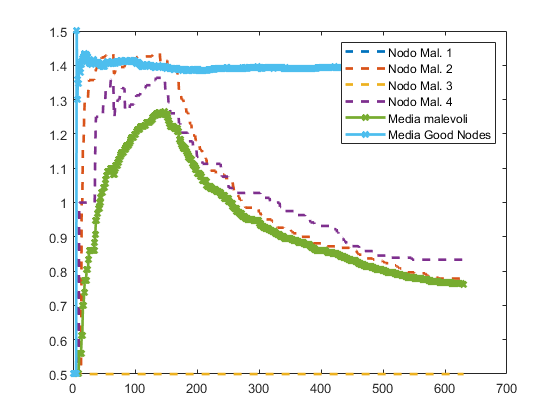


scheduler_temp=sort_scheduler_temp(scheduler_temp);
scheduler=sort_scheduler(scheduler);
mean_queue=mean(queue_array);

% for index_k = 1:length(reputation1)
%     %% mean malicius
%     time_array_mal_mean(index_k) = time_array1(index_k);
%     reputation_mal_mean(index_k) = (reputation1(index_k) + reputation2(index_k) + reputation3(index_k) + reputation4(index_k))/4;
%     %% end mean malicius
% end

figure(1);
grid on;
plot(time_array1, reputation1, '--', 'LineWidth', 2);
hold on;
plot(time_array2, reputation2, '--', 'LineWidth', 2);
hold on;
plot(time_array3, reputation3, '--', 'LineWidth', 2);
hold on;
plot(time_array4, reputation4, '--', 'LineWidth', 2);
hold on;
plot(time_array5, reputation5 , '-x', 'LineWidth', 2);
hold on;
plot(time_array10, reputation_good , '-x', 'LineWidth', 2);
lgnStr = ["Nodo Mal. 1","Nodo Mal. 2","Nodo Mal. 3","Nodo Mal. 4","Media malevoli", "Media Good Nodes"];
legend(lgnStr);

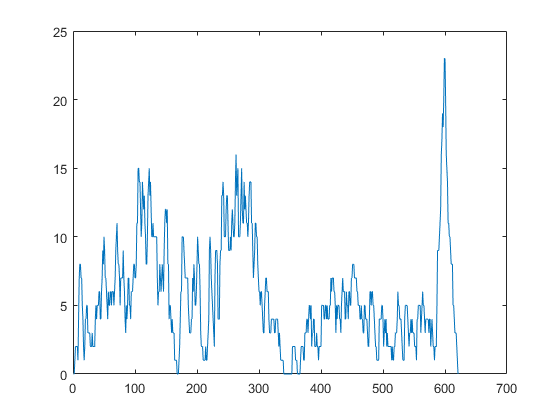

figure(2);
grid on;
plot(queue_size_array);

%clearvars -except service_array master_array device_array num_serv D M n_r check_resource scheduler lambda scheduler_temp t n_accomplished queue_size time_array10 reputation_mean time_array1 reputation1 reputation2 reputation3 reputation4 n1 n2 n3 n4 time_array n_accomplished_array queue_size_array